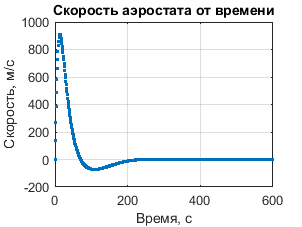

clc; clear;


m = 0.2; % кг
V = 3; % м^3
g = 9.81; 
k = 0.01;

dt = 1;
t = 0:dt:600;

v = zeros(size(t));
y = zeros(size(t));

for i = 1:length(t)-1
    Fa = g * V * airDensity(y(i)); % Сила Архимеда
    Ft = -k * v(i);
    Fg = -m * g;
    v(i+1) = v(i) + (Fa + Fg+ Ft) / m * dt;
    y(i+1) = y(i) + v(i+1) * dt;
end

plot(t, v, '.')
xlabel('Время, с')
ylabel('Скорость, м/с')
title('Скорость аэростата от времени')
grid on
saveas(gcf, 'ball_speed.png')

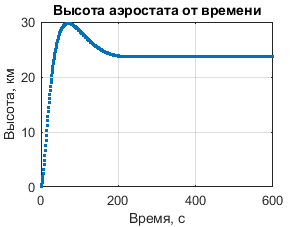


plot(t, y/1000, '.')
xlabel('Время, с')
ylabel('Высота, км')
title('Высота аэростата от времени')
grid on
saveas(gcf, 'ball_coord.png')

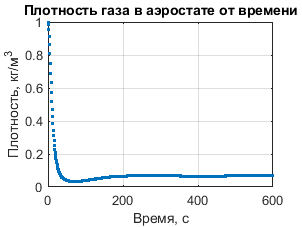


plot(t, airDensity(y), '.')
xlabel('Время, с')
ylabel('Плотность, кг/м^3')
title('Плотность газа в аэростате от времени')
grid on
saveas(gcf, 'ball_density.png')